# Ex 1 - Consensus [part 2]

clear variables
close all
clc

## Rng seed

rng(1)

## Graph generation

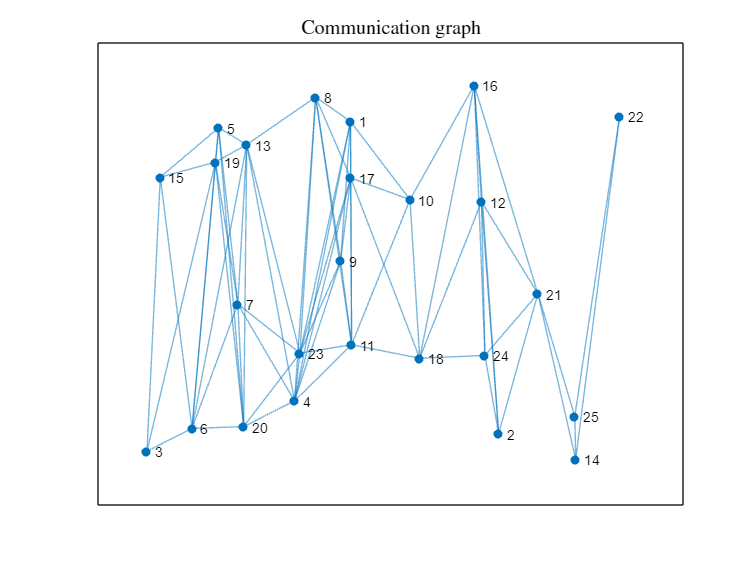

N = 25;             % number of nodes
r = 0.2;            % radius of random graph
sim_len = 1000;     % simulations length

[A_conn, ~, pos] = random_graph(N,r,true);  % generate connected random graph

#### Initialize

v = rand(N,1);      % observations
v_avg = mean(v);    % value of average consensus

#### Modify graph to make it not connected

Manually delete some of the connections in the graph to make it not connected. The graph is always the same thanks to the seed initialization above, so the connections to remove are always the same.

A = A_conn;
A(10, 16) = 0;
A(16, 10) = 0;
A(16, 18) = 0;
A(18, 16) = 0;
A(12, 18) = 0;
A(18, 12) = 0;
A(18, 24) = 0;
A(24, 18) = 0;

#### Plot resulting graph

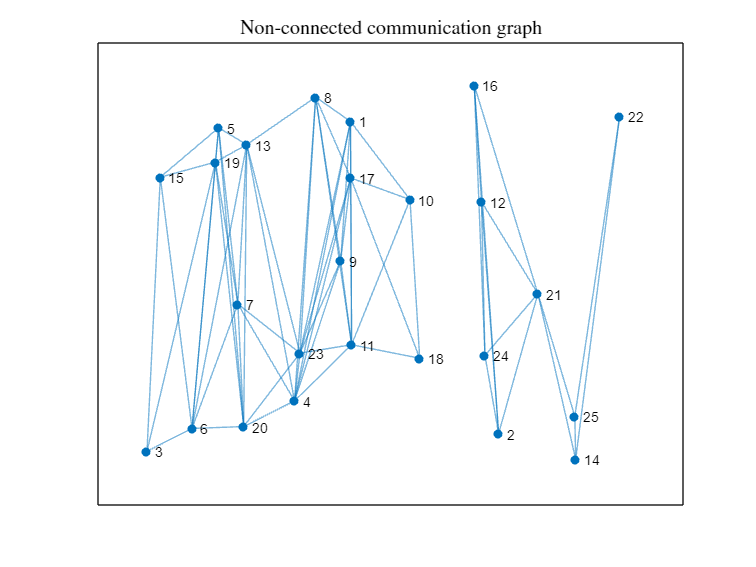

G = graph(A); % create graph object
    
figure()
    h = plot(G);
    h.XData = pos(:,1);
    h.YData = pos(:,2);
    xlim([-0.1 1.1])
    ylim([-0.1 1.1])
    title('Non-connected communication graph','Interpreter','latex')

#### Re-compute relevant matrices

D = diag(sum(A,1)); % degree matrix
L = D - A;          % laplacian matrix

## Average consensus

Compute consensus both for the disconnected graph and (below) for the initial connected graph. The second plot is to be used as a reference.

#### Non-connected graph

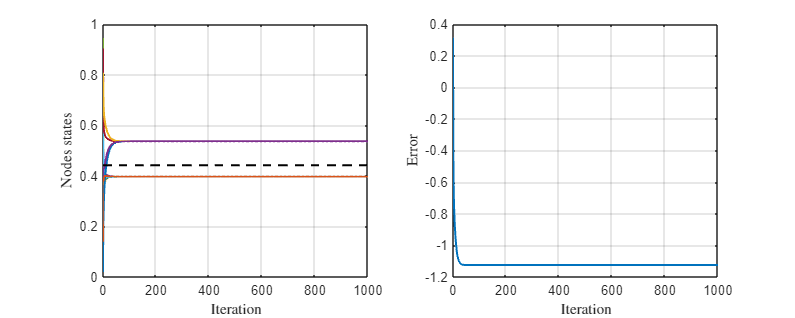

% generate consensus matrix
eps = 1/max(diag(L)); % choose epsilon
P = eye(N) - eps*L; % design consensus matrix

X = [v, zeros(N,sim_len)]; % trajectories of nodes states

% compute average consensus
for k = 1:sim_len
    
    X(:,k+1) = P*X(:,k); % update nodes' states
    
end

% plot result
plot_results(X, v_avg)

#### Connected graph consensus

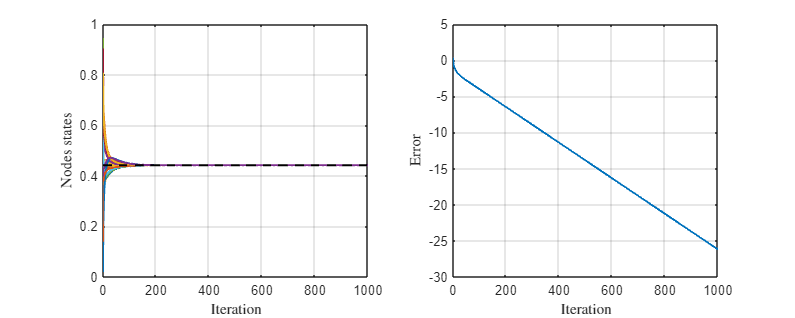

% compute missing matrices
D_conn = diag(sum(A_conn, 1));
L_conn = D_conn - A_conn;

% generate consensus matrix
eps_conn = 1/max(diag(L_conn)); % choose epsilon
P_conn = eye(N) - eps_conn*L_conn; % design consensus matrix

X_conn = [v, zeros(N,sim_len)]; % trajectories of nodes states

% compute average consensus
for k = 1:sim_len
    
    X_conn(:,k+1) = P_conn*X_conn(:,k); % update nodes' states

end

% plot result
plot_results(X_conn, v_avg)